# Aufgabe 3 (Pulsbreite eines Femtosekundenlasers)

(weitere Erklärungen zum Hintergrund dieser Aufgabe gibt’s vor Ort beim Praktikum.)

Femtosekundenlaser erzeugen Lichtpulse, die nur wenige Femtosekunden dauern (1 Femtosekunde =${10}^{-15}$ Sekunden) und haben viele Anwendungen in Wissenschaft und Technik. Um die Form eines solchen Lichtpulses genauer zu bestimmen, wird oft die *FROG*-Technik genutzt, bei der die Autokorrelation des Lichtpulses im Frequenzbereich gemessen wird. Im Ordner `Daten/FrogTraces` befindet sich eine Sammlung sogenannter *Frog*-Traces. Dabei handelt es sich um Spektrogramme der Autokorrelation von kurzen Laserpulsen.

Der interessierte Leser findet hier weitere Informationen: [https://uol.de/f/5/inst/physik/ag/ukd/Publikationen/2007/Skript-Version30.pdf.](https://uol.de/f/5/inst/physik/ag/ukd/Publikationen/2007/Skript-Version30.pdf.) Ab Seite 70 werden die Frog-Traces für einige Pulsformen dargestellt. 

In dieser Aufgabe geht es darum, ein vollverbundenes Netz zu entwickeln, das die Pulsbreite anhand des Spektrogramms des Pulses vorhersagt. Die Pulsbreite für jedes Spektrogramm ist in den Dateien `MetaDataTrain.csv` und `MetaDataTest.csv `gegeben.

### Aufgabe 3 (a) Daten laden

Laden Sie die Trainingsdaten und bringen Sie sie in eine für vollverbundene Netze geeignete Form.

dataDir = fullfile('Daten', 'FrogTraces'); 
trainDir = fullfile(dataDir, 'train');
testDir = fullfile(dataDir, 'test');
metaDataTrain = readtable(fullfile(trainDir, 'MetaDataTrain.csv'));
metaDataTest = readtable(fullfile(testDir, 'MetaDataTest.csv'));
nTrain = size(metaDataTrain, 1);
nTest = size(metaDataTest, 1);

Ein Bild laden und ansehen:

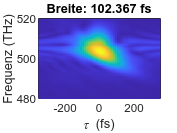

img = imread(fullfile(trainDir, [metaDataTrain.Name{1} '.png']));
imSize = size(img);
pc = pcolor(linspace(-350, 350, imSize(1)), ...
   linspace(480, 520, imSize(2)), img);
pc.LineStyle='none';
title(sprintf('Breite: %.3f fs', metaDataTrain.RMSWidth(1)));
xlabel('\tau (fs)');
ylabel('Frequenz (THz)');

Trainingsdaten einlesen:

P = imSize(1)*imSize(2);  % Anzahl Pixel (= Merkmale)
tainMat = zeros(nTrain, P);

for i = 1:nTrain
   img = imread(fullfile(trainDir, [metaDataTrain.Name{i} '.png']));
   % img in die i-te Zeile schreiben von trainMat schreiben:
   % TODO: ab hier weiter machen!
end
% Zielgroessen aus Tabelle holen:
trainTarget = metaDataTrain.RMSWidth;
% histogram(trainTarget);

### Aufgabe 3 (b) Vollverbundes Netz entwerfen

Entwickeln Sie ein vollverbundenes, neuronales Netz, das die Pulsbreite möglichst gut vorhersagt.

### Aufgabe 3 (c) Anwenden auf Testdaten 

Laden Sie die Testdaten und überprüfen Sie damit die Qualität Ihres in Teil (b) entwickelten Netzes.